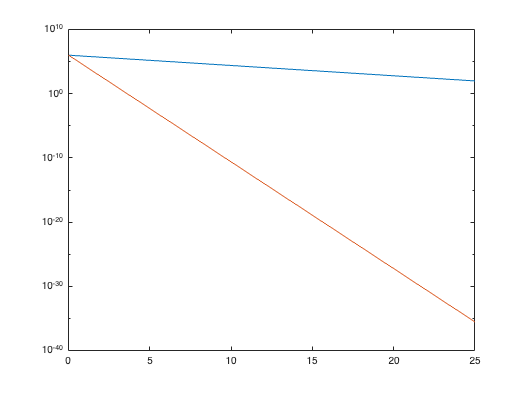

lft_x = linspace(0,25,256);
tau1 = 2.706;
tau2 = 0.2613;
TP = 1000000;
lft_y1 = TP*exp(-lft_x/tau1);
lft_y2 = TP*exp(-lft_x/tau2);

figure
semilogy(lft_x, lft_y1)
hold on
semilogy(lft_x, lft_y2)

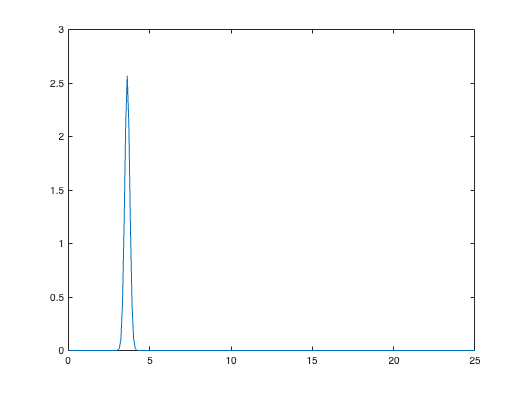

width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

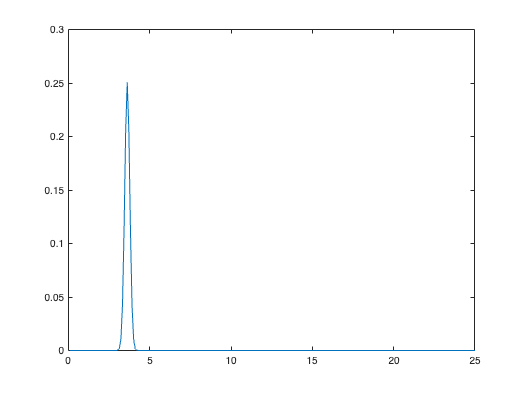

Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)


find(Gaussian_y == max(Gaussian_y))

ans = 37

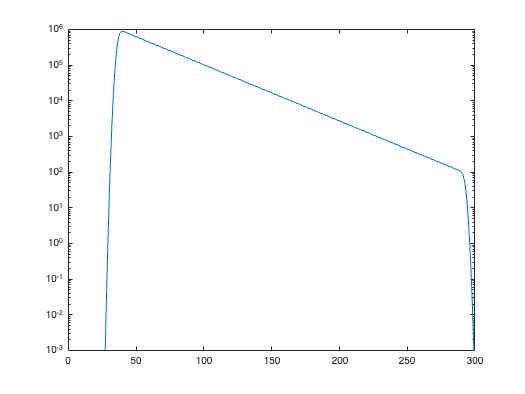

lft_y1_conv = conv(lft_y1, Gaussian_y);

figure
semilogy(lft_y1_conv)
ylim([0.001 1000000])


find(lft_y1_conv == max(lft_y1_conv))

ans = 40

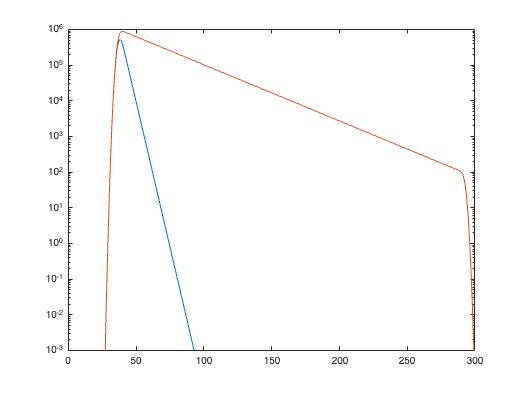

lft_y2_conv = conv(lft_y2, Gaussian_y);

figure
semilogy(lft_y2_conv)
hold on
semilogy(lft_y1_conv)
ylim([0.001 1000000])


find(lft_y2_conv == max(lft_y2_conv))

ans = 38

max(lft_y1_conv)/sum(lft_y1_conv)

ans = 0.0315